# Preprocessing Data

whalesRaw = importWhaleData("BlueWhaleData.csv")

whalesRaw = 16249×8 table
           ID                  timestamp           longitude    latitude    sensorQuality    sensorMeasurements    sensorType    markedOutliers
    ________________    _______________________    _________    ________    _____________    __________________    __________    ______________

    1993CA-Bmu-00834    1993-08-29 01:13:00.000     -122.43      37.058      <undefined>            NaN               gps              ""      
    1993CA-Bmu-10823    1993-08-28 18:20:00.000     -122.41      37.012      <undefined>            NaN               gps              ""      
    1993CA-Bmu-10833    1993-08-28 18:54:00.000     -122.42      37.022      <undefined>            NaN               gps    

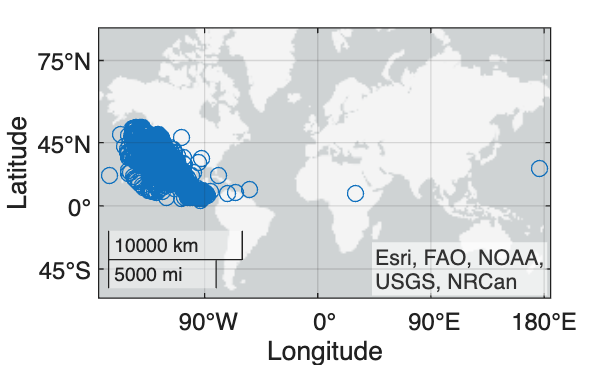


geoscatter(whalesRaw.latitude,whalesRaw.longitude)

## 1. Missing Data

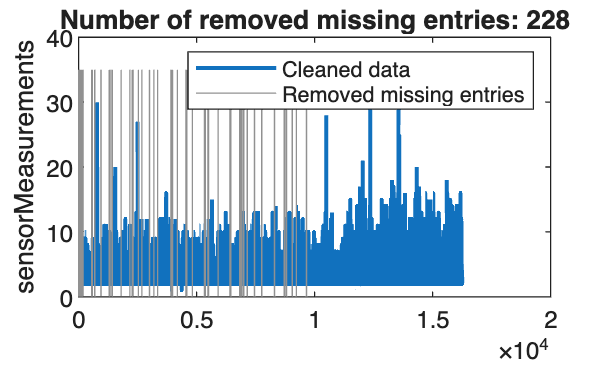

% Remove missing data
[whaleClean1,missingIndices] = rmmissing(whalesRaw, ...
    DataVariables="sensorMeasurements");

% Display results
figure

% Plot cleaned data
plot(find(~missingIndices),whaleClean1.sensorMeasurements,SeriesIndex=1, ...
    LineWidth=1.5,DisplayName="Cleaned data")
hold on

% Plot removed missing entries
x = repelem(find(missingIndices),3);
y = repmat([ylim(gca) missing]',nnz(missingIndices),1);
plot(x,y,"Color",[145 145 145]/255,DisplayName="Removed missing entries")
title("Number of removed missing entries: " + nnz(missingIndices))

hold off
legend
ylabel("sensorMeasurements")

clear x y

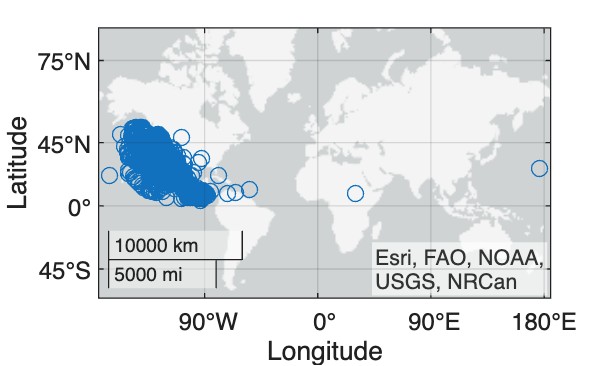

geoscatter(whaleClean1.latitude, whaleClean1.longitude)

## 2. Handling Low Quality Data

rowsToKeep = whaleClean1.sensorQuality ~= "Z"

rowsToKeep = 16021×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


whaleClean2 = whaleClean1(rowsToKeep,:)

whaleClean2 = 14830×8 table
           ID                  timestamp           longitude    latitude    sensorQuality    sensorMeasurements        sensorType         markedOutliers
    ________________    _______________________    _________    ________    _____________    __________________    ___________________    ______________

    1993CA-Bmu-00834    1993-08-29 01:23:17.000     -122.41      36.981           1                  4             argos-doppler-shift        ""        
    1993CA-Bmu-00834    1993-08-31 13:04:34.000     -122.79      37.637           B                  2             argos-doppler-shift        ""        
    1993CA-Bmu-00834    1993-09-01 01:57:39.000     -122.83      37.166           B    

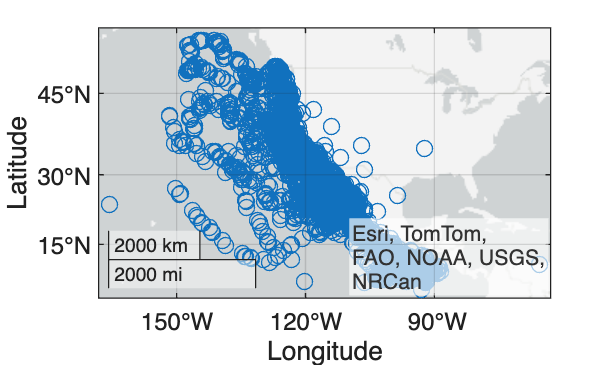

geoscatter(whaleClean2.latitude, whaleClean2.longitude)

## 3. Handling Outliers

rowsToKeep = whaleClean2.markedOutliers ~= "true"

rowsToKeep = 14830×1 logical array
   1
   1
   1
   0
   0
   0
   0
   1
   0
   1
   1
   1
   1
   1
   1


whaleClean3 = whaleClean2(rowsToKeep,:)

whaleClean3 = 14514×8 table
           ID                  timestamp           longitude    latitude    sensorQuality    sensorMeasurements        sensorType         markedOutliers
    ________________    _______________________    _________    ________    _____________    __________________    ___________________    ______________

    1993CA-Bmu-00834    1993-08-29 01:23:17.000     -122.41      36.981           1                  4             argos-doppler-shift          ""      
    1993CA-Bmu-00834    1993-08-31 13:04:34.000     -122.79      37.637           B                  2             argos-doppler-shift          ""      
    1993CA-Bmu-00834    1993-09-01 01:57:39.000     -122.83      37.166           B    

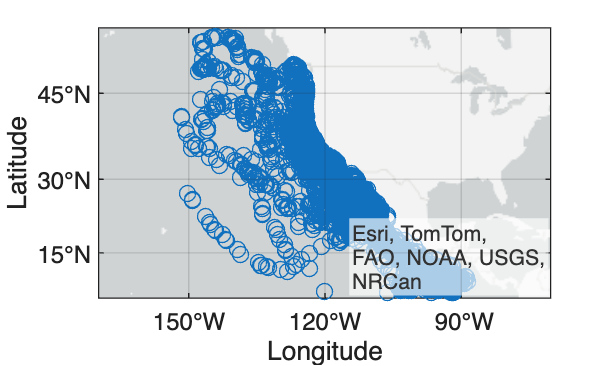


geoscatter(whaleClean3.latitude, whaleClean3.longitude)

whales = whaleClean3

whales = 14514×8 table
           ID                  timestamp           longitude    latitude    sensorQuality    sensorMeasurements        sensorType         markedOutliers
    ________________    _______________________    _________    ________    _____________    __________________    ___________________    ______________

    1993CA-Bmu-00834    1993-08-29 01:23:17.000     -122.41      36.981           1                  4             argos-doppler-shift          ""      
    1993CA-Bmu-00834    1993-08-31 13:04:34.000     -122.79      37.637           B                  2             argos-doppler-shift          ""      
    1993CA-Bmu-00834    1993-09-01 01:57:39.000     -122.83      37.166           B         

save cleanWhaleData whales